## Mass damper spring system

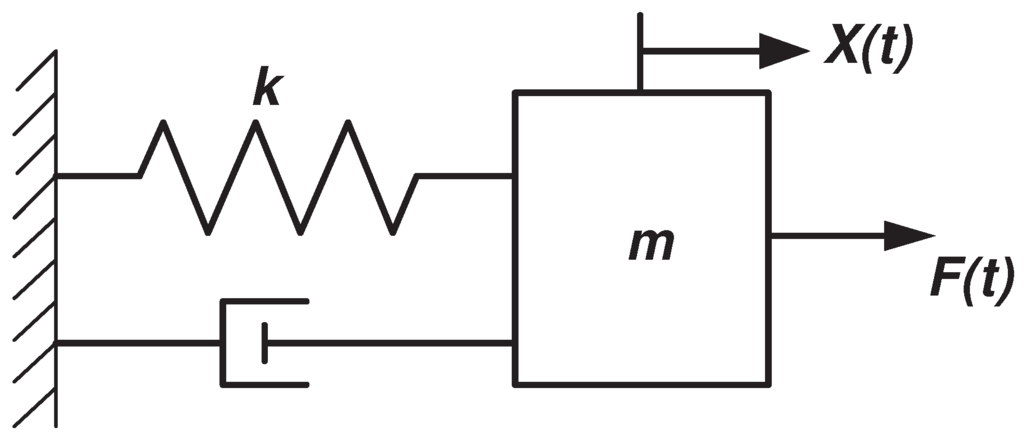

We will consider the following system. This system has the following state space representation:


$$\pmatrix{\dot{x} \cr \ddot{x}} = 
\pmatrix{0 & 1 \cr \frac{-k}{M} & \frac{-f_v}{M}}
\pmatrix{x \cr \dot{x}} +
\pmatrix{0 \cr \frac{1}{M}} u$$


k = 1;
M = 1;
f = 1;
A = [0 1 ; -k/M -f/M];
B = [0 ; 1/M];
C = [1 0 ; 0 1];
D = [];
sys_mds = ss(A,B,C,D);

For this example we will consider data generated by the impulse response of this system.

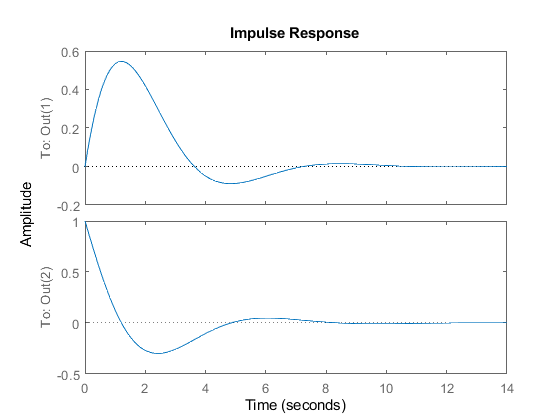

impulse(sys_mds)

[y,t,x] = impulse(sys_mds);

### Defining the data

We will first consider all 150 datapoints generated. Since we are considering the impulse responce we have that our input vector is equal to [1 0 0 ...] and is of size 149x1.

U = zeros(1,149);
U(1) = 1;
X = x';

### System identification

We can check if the data is informative for system identification by using `[bool, A, B] = isIdentifiable(X, U)`. For this to be the case we need that the data is full rank, i.e.:


$$rank \pmatrix{X_- \cr U_-} = n + m$$


Since we use the impulse function we know that the first collumn will be linearly independant. Hence we only need 2 other columns to be linearly independant. From this we can see that the use of 150 data points is a bit eccesive, hence we also consider some cases below where we reduce the amount of data points.

[bool, A_s, B_s] = isIdentifiable(X, U)

bool = logical
   1


A_s =    0.995888646556444   0.087864828422739
  -0.087864828422739   0.908023818133706


B_s = 	1.0e+-16 *

   0.328240155363125
  -0.307658977543180


We will use the received A and B matrix to verify the data.

#### Verifying results

We can check the validity of the results by comparing them against the descrete time version of the system that we used. To get the discrete time system we use the [`sysd = c2d(sysc,Ts)`](https://nl.mathworks.com/help/control/ref/c2d.html#d122e26414) function provided by matlab.

sys_mds_d = c2d(sys_mds,t0);

disp("Difference between actual A and A_s");

Difference between actual A and A_s


A_s - sys_mds_d.A

ans = 	1.0e+-15 *

                   0  -0.013877787807814
                   0   0.666133814775094


disp("Difference between actual B and B_s");

Difference between actual B and B_s


B_s - sys_mds_d.B

ans =   -0.004111353443556
  -0.087864828422739


As we can see we do get an accurate `A` (up to machine presision), but the `B` is off. This is probably due to the use of the impulse responce which is practically 0.

#### How much data is needed and what is the precision

We will now look at how much data we need for system identification, for this we will check the first `n` entries of the data where `n` is from `1` to `10`. We will also use these results to check the consistency of the result based on the amount of data provided.

valid = [];
a11 = [];
a12 = [];
a21 = [];
a22 = [];
b1  = [];
b2  = [];
for idx = 1:10
    X_temp = X(:,1:idx+1);
    U_temp = U(:,1:idx);
    if isIdentifiable(X_temp, U_temp)
        valid = [valid idx];
        [~, A_temp, B_temp] = isIdentifiable(X_temp, U_temp);
        a11 = [a11 A_temp(1,1)];
        a12 = [a12 A_temp(1,2)];
        a21 = [a21 A_temp(2,1)];
        a22 = [a22 A_temp(2,2)];
        b1  = [b2  B_temp(1)];
        b2  = [b2  B_temp(2)];
    end
end

From this we can inspect the valid array and see for how many data points the data is informative for system identification. As we noted earlier, we only needed 2 more linearly independant collumns, which where the 2nd and 3rd collumn in this case.

disp("Array noting if the system is informative for identification based on the amount of data points used:")

Array noting if the system is informative for identification based on the amount of data points used:


valid

valid =      3     4     5     6     7     8     9    10


We can also check to see the larges difference between values that we received for the `A` and `B` matrix. As we can see the `A` and `B` are unique opto working precision.

disp("The maximal difference between the returned A and B matrices.")

The maximal difference between the returned A and B matrices.


A_delta = [max(a11-min(a11)) max(a12-min(a12));
           max(a21-min(a21)) max(a22-min(a22))]

A_delta = 	1.0e+-14 *

   0.233146835171283   0.088817841970013
   0.577315972805081   0.144328993201270


B_delta = [max(b1-min(b1));
           max(b2-min(b2))]

B_delta = 	1.0e+-14 *

   0.174860126378462
   0.174860126378462


### Controllability

In this section we will see if the data is informative for controllability. For this we only need the state data. We can check this using the `bool = isControllable(X) `command.

disp("The data is informative for controllability?");

The data is informative for controllability?


isControllable(X)

ans = logical
   0


As we can see the data is not informative for controllability. This is as expected since `B_s` is zero up to working presision`. `Hence the controllability matrix is zero and thus the system is not controllable.

### Stabilisability

In this section we will see if the data is informative for stabilizability. Simmiler to controllability, we only need to consider the state data. We can check if the data is informative for stabilizability by using the `bool = isStabilisable(X)` function.

disp("The data is informative for system stabilisability?");

The data is informative for system stabilisability?


isStabilisable(X)

ans = logical
   0


### Deadbeat Control

### State feedback